    clc; clear; close all; format short eng;

% Carrega as variaveis
load("./dados_2m_CLV.mat")
load("./dados_2m_SLV.mat")

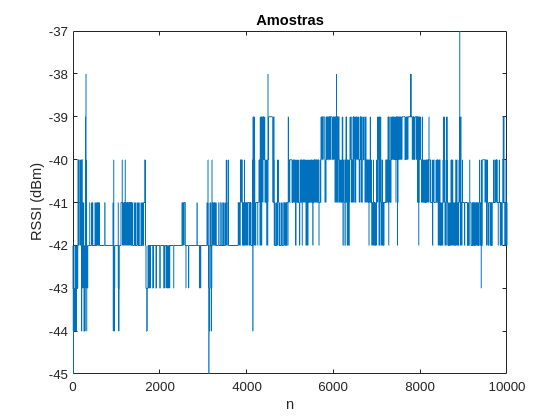

% Extrai os dados da terceira coluna (RSSI em dBm)
RSSIdBm_CLV = dados_2m_CLV(:, 3);
figure
plot(linspace(1, 10000, 10000), RSSIdBm_CLV);
title('Amostras');
xlabel('n');
ylabel('RSSI (dBm)');

% Converte para mW
RSSI = 10.^(RSSIdBm_CLV/10); %mW

% Média de RSSI
RSSI_barra = mean(RSSI); %mW

% calculo de h
h = sqrt(RSSI/RSSI_barra)

h =    880.4887e-003
   784.7364e-003
   880.4887e-003
   880.4887e-003
   784.7364e-003
   699.3971e-003
   699.3971e-003
   699.3971e-003
   699.3971e-003
   623.3383e-003


% Teste se E[h^2] = 1
M_2 = mean(h.^2)

M_2 =      1.0000e+000


% teste com p = 2, idealmente p >= 2
p = 2

p =      2.0000e+000


% [5, eq.9]
% calculo de m utlizando etimadores de momento generalizado
m = mean(h.^(1/p)) / (2*p*( mean(h.^(1/p + 2)) - mean(h.^(1/p)) ))

m =     15.3585e+000


% Plota o hitograma e pdf nakagami-m
h_values = linspace(0, max(h), 1000);
pdf_h = (2 * m^m * h_values.^(2*m - 1)) ./ (gamma(m)) .* exp(-m * h_values.^2)

pdf_h =      0.0000e+000    64.7490e-078    57.1358e-069     9.7665e-063    50.4007e-060    38.2093e-057     8.6104e-054   839.9838e-054    44.3992e-051     1.4696e-048    33.6252e-048   570.6763e-048     7.5679e-045    81.5822e-045   737.2029e-045     5.7218e-042    38.9004e-042   235.4136e-042     1.2851e-039     6.3992e-039    29.3410e-039   124.8781e-039   496.7830e-039     1.8583e-036     6.5709e-036    22.0632e-036    70.6339e-036   216.3811e-036   636.3226e-036     1.8015e-033     4.9226e-033    13.0131e-033    33.3499e-033    83.0170e-033   201.0714e-033   474.6042e-033     1.0933e-030     2.4612e-030     5.4213e-030    11.6972e-030    24.7478e-030    51.3915e-030   104.8415e-030   210.2927e-030   415.0499e-030   806.6323e-030     1.5447e-027     2.9166e-027     5.4329e-027     9.9898e-027


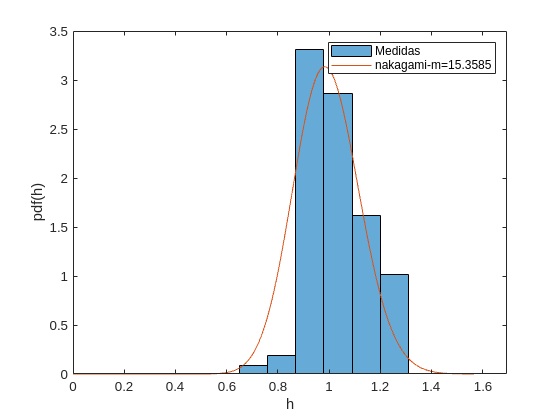

histogram(h, 10, 'Normalization', 'pdf');
hold on
plot(h_values, pdf_h);
legend('Medidas', ['nakagami-m=' num2str(m)])
xlabel('h');
ylabel('pdf(h)')
hold off